**ФЕДЕРАЛЬНОЕ АГЕНТСТВО ЖЕЛЕЗНОДОРОЖНОГО ТРАНСПОРТА **

Федеральное государственное бюджетное образовательное учреждение высшего образования

**«Петербургский государственный университет путей сообщения **

**Императора Александра ****I****»**

**(ФГБОУ ВО ПГУПС)**

Факультет «Транспортные и энергетические системы»

Кафедра «Электрическая тяга»

Специальность 25.05.03 «Подвижной состав железных дорог»

Специализация «Электрический транспорт»

Дисциплина «Компьютерное моделирование электрооборудования ЭПС»

**Отчет по ТЗ №2**

**«Разработка математической модели понижающего преобразователя (ПП)»**

**Вариант №5**

 **Выполнил студент**

 **Курс: 5**

**Группа: ПС-003**

Дулепов И.Г.

                                                                                     ______________      

                                                                                      (Дата, подпись)   

  **Руководитель                                                                                                                                                                   **Сычугов А.Н.                                                                                                                                   

                                                                                    ______________      

                                                                                      (Дата, подпись)                                                        

Санкт-Петербург 

2024

**Типовая задача №2.  Моделирование тягового преобразователя, питающего коллекторный ТЭД:**

## **Введение**

**Цель работы: **Построение математической модели широтно-импульсного понижающего преобразователя напряжения в соответствии с исходными данными, построение внешних и регулировочных характеристик преобразователя на основе смоделированных данных в диапазоне коэффициента заполнения 0,1-0,99.

На рисунке 1 представлена схема импульсного регулирования напряжения двигателя постоянного тока независимого возбуждения в соответствии с вариантом типового задания.

 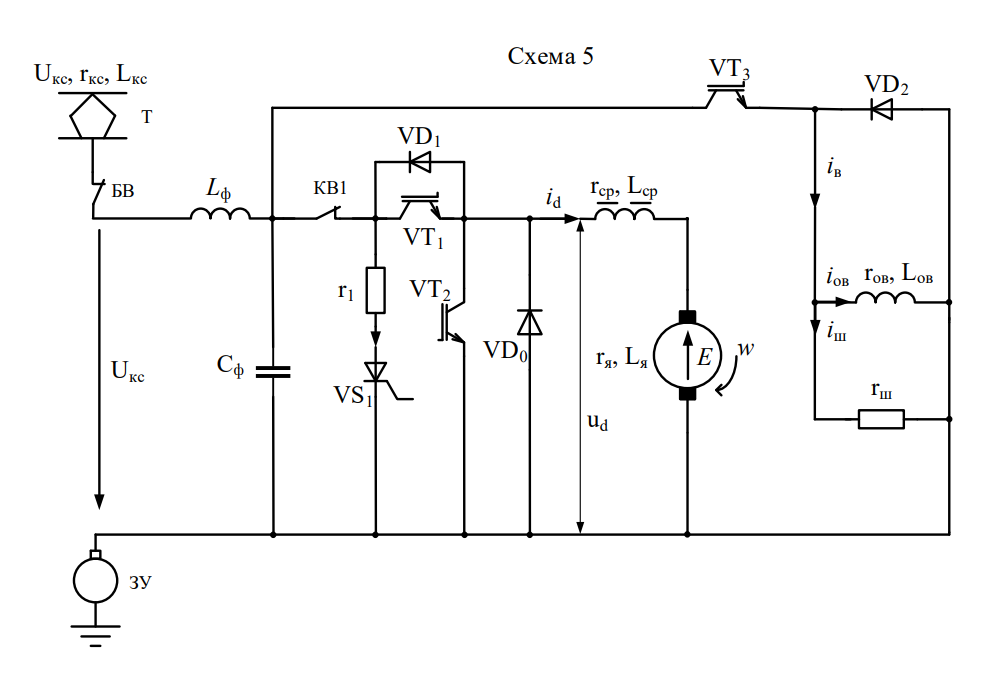

Рисунок 1. Схема импульсного регулирования напряжения при независимом возбуждении ТЭД.

## **1. Схема модели широтно-импульсного преобразователя в Simulink:**

На рисунке 2 представлена математическая модель понижающего ШИП, смоделированная в Simulink.

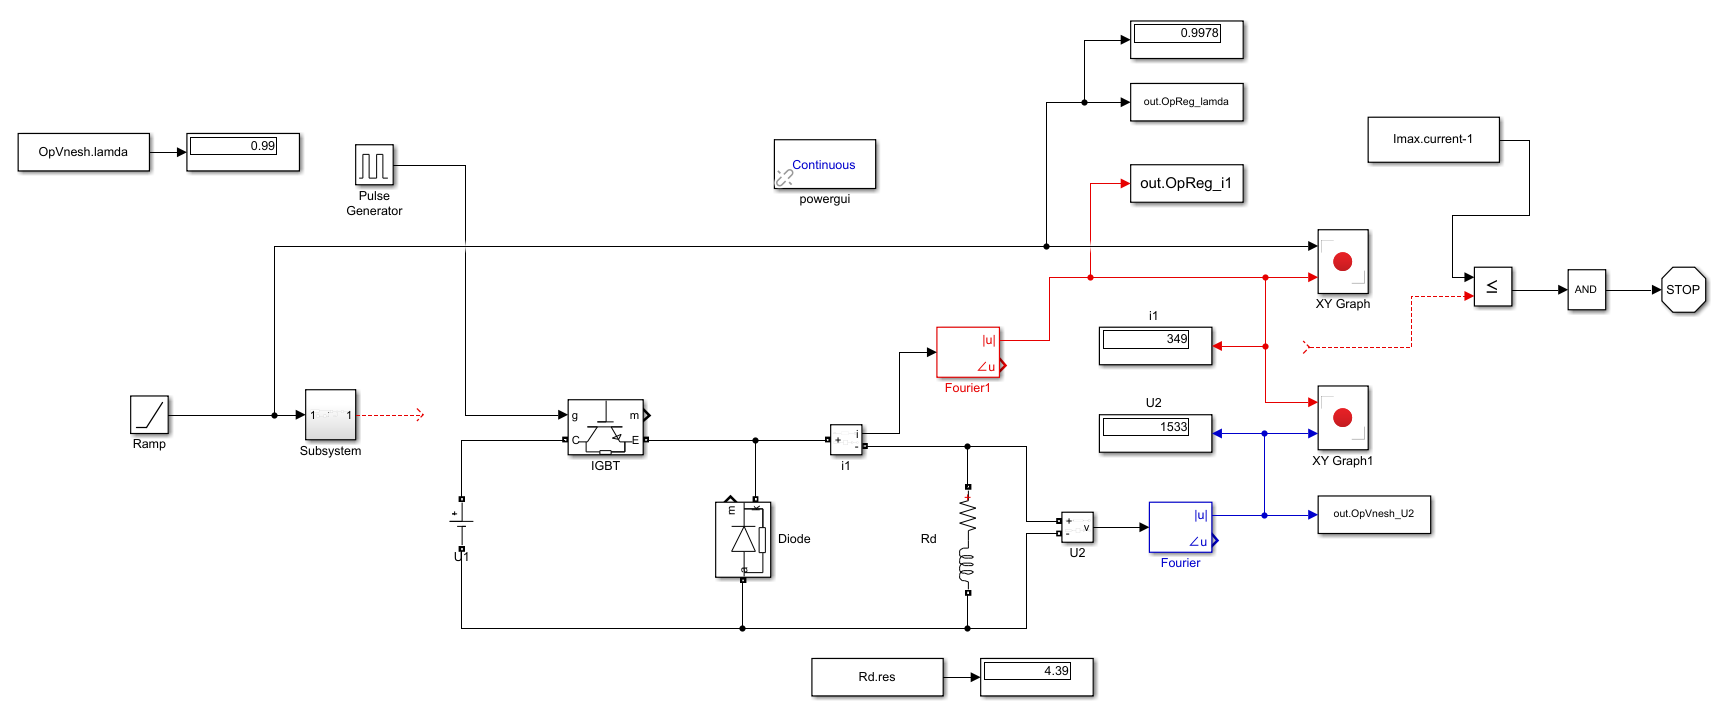

Рисунок 2. Математическая модель понижающего ШИП, смоделированная в Simulink.

Структура блока «Subsystem» (блока формирования импульсов) для снятия регулировочной характеристики ШИП показана на рисунке 3.

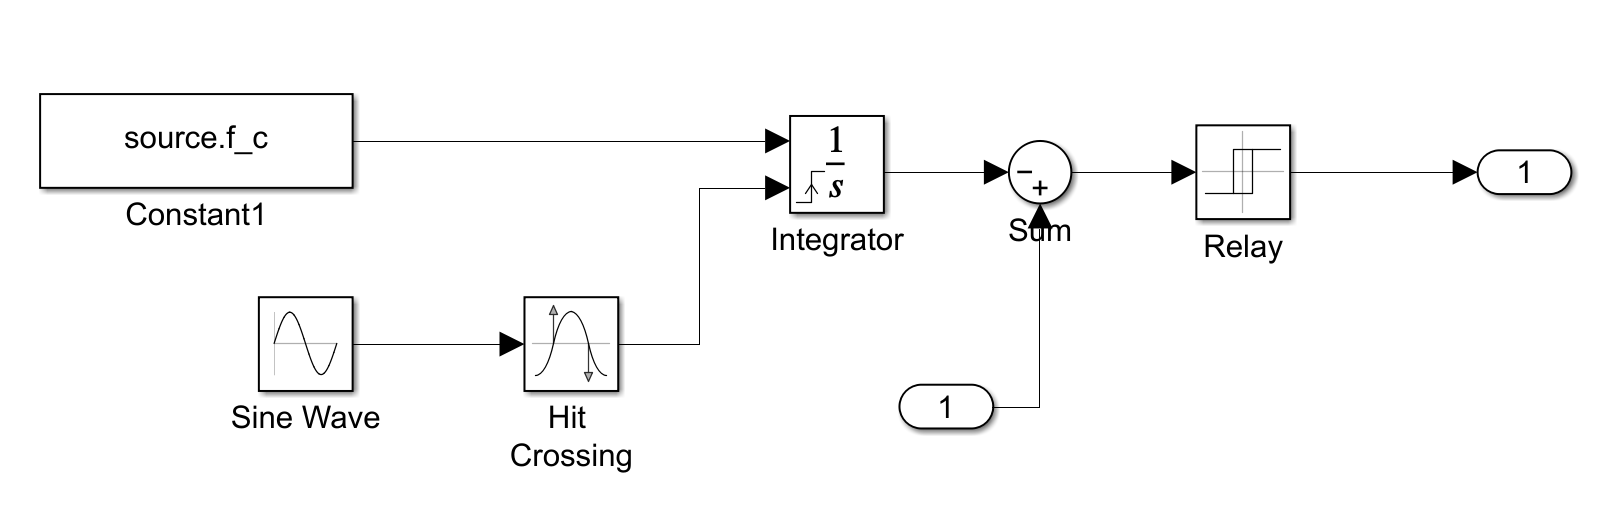

Рисунок 3. Блок «Subsystem» (блок формирования импульсов)

## **  2. Задание исходных данных:**

**  Задание параметров тягового преобразователя:**

### 2.1. Частота работы преобразователя, Гц:

source.f_c = 700;

Номинальный ток ТЭД (Iян=Imax), А:

Imax.current = 350;

### **2.2. Напряжение, подводимое к одному ТЭД (U1):**

где     k – число последовательно соединенных ТЭД

k = 2;

         Uкс - напряжение контактной сети на токоприемнике, высчитываемое по формуле:

U_tp = 3450; %Напряжение тяговой подстанции, В.

          Rтп - суммарное активное сопротивление тяговой подстанции приведенное к тяговой обмотке трансформатора, Ом.:

где Rпрт- активное сопротивление **трансформатора**, работающего в схеме **12-ти пульсового выпрямителя** с последовательным соединением мостов, Ом (тип трансформатора **ТРДП -12500/ЖУ1**):

где U2л – линейное напряжение выпрямительной обмотки преобразовательного трансформатора, В;

transpulse12.U_2l = 1.305*10^3; %В

      Sн – мощность трансформатора, кВА,

transpulse12.S_n = 11400; %кВА

      ΔPк – потери короткого замыкания, кВт.

transpulse12.deltaP_k = 71.5; %кВТ
R_prt = (((transpulse12.U_2l^2)*transpulse12.deltaP_k)/(transpulse12.S_n^2))*(10^(-3));

      Rпнт - активное сопротивление **понизительного трансформатора**, Ом (тип трансформатора **ТМН - 16000/110-66**):

где U2л – линейное напряжение выпрямительной обмотки понизительного трансформатора, В; 

transponis.U_2l = 6.6*10^3; %В

Sн – мощность трансформатора, кВА, 

transponis.S_n = 16000; %кВА

ΔPк – потери короткого замыкания, кВт.

transponis.deltaP_k = 26; %кВт
R_pnt = (((transponis.U_2l^2)*transponis.deltaP_k)/(transponis.S_n^2))*(10^(-3));

R1 - Активное сопротивление первичной сети, Ом:

где X1 - индуктивное сопротивление первичной сети:

где Sк – мощность к.з. на шинах тяговой подстанции. Примем  Sк=1500МВ*А для питающей сети напряжением Uпс=110 кВ.

S_k = 1500;
X_1 = (transponis.U_2l^2)/(S_k*(10^6));
R_1 = 0.15*X_1;

       Rш – активное сопротивление то копроводов в выпрямительной части схемы. Сопротивлением Rш  при выполнении расчетов можно принебречь.

      Rвп - активное сопротивление 12-ти пульсового выпрямителя: 

где rт– активное сопротивление силового диода, Ом (**Силовой диод** по табл.9 методич. указаний **Д543-630**); 

      a – число последовательно соединённых диодов в плече выпрямителя, 

      S – число параллельно  соединённых диодов в плече выпрямителя.

a = 1;
S = 1;
Diode.r_t = 1.2*(10^-3);
R_vp = 4*(a/S)*Diode.r_t;

    Rсгр – активное сопротивление  сглаживающего реактора тяговой подстанции примем равным 0.006 Ом  (РБФАУ-6500):

R_sgr = 0.006;

    Тогда:

R_tp = R_prt+R_pnt+R_1+R_vp+R_sgr

R_tp = 0.0205

          Rтс - активное сопротивление ТС (тяговой сети) складывается из сопротивления контактного рельса и сопротивления рельсовой цепи обратного тока, зависит от местоположения ЭПС на фидерной зоне и рассчитывается по следующим зависимостям, Ом: 

где Rкр – электрическое сопротивление контактного рельса, по ТУ 14 2-82-73, 

R_kr = 0.0189; %Ом/км.

Rрс – сопротивление рельсовой цепи, Ом/км, 

В рельсовых цепях предусматривают в среднем до 8 ÷ 12 изолирующих стыков на 1 км пути. Сопротивление рельсовой цепи с учётом сопротивления включенных в сеть дроссельных стыков по вычисляем формуле:

где rр - сопротивление 1 км рельсовой нити, 

r_r = 0.0254; %Ом/км для ходового рельса типа Р65

0,036 - отношение сопротивления одного дроссель ногостыка к сопротивлению 1 км целого рельса; 

m - число изолирующих стыков (допущено примем m = 10);

m = 10;

n - число параллельно включенных рельсовых нитей (для одного пути n= 2, для двух путей n = 4).

n = 4;

l = lтп –  протяженность контактной и рельсовой цепей (расстояние от ЭПС до тяговой подстанции), км.

l = 9; %км.
R_rs = r_r*(l+0.036*m)/n;

Тогда:

R_ts = R_kr*l+R_rs

R_ts = 0.2295

Количество тяговых секций ЭПС:

N_ts = 3; %Согласно исходным данным

a - число параллельных ветвей ТЭД в силовой схеме тяговой секции.

a_ted = 2;

Ток ТЭД в расчетном режиме Iя:

I_ust = 250; %А.

Отсюда:

U_ks = U_tp-(R_tp+R_ts)*N_ts*a_ted*I_ust

U_ks = 3.0749e+03

U_1 = U_ks/k

U_1 = 1.5375e+03

### 2.3. Параметры IGBT транзистора:

В качестве главного силового полупроводникового прибора VT1 был выбран IGBT-транзистор «Infineon FZ750R65KE3», паспортные данные транзистора привидены в приложении 1.

Рассчитываем на основе паспортных данных транзистора:

1) Lm (Module inductance), нГн:

Inductance, Lon (Н):

IGBT.L_on = 18*10^-9; %Гн.

Resistance Ron (Ohms) (определяем по внешней характеристике транзистора (приложение 1)):

**Ausgangskennlinienfeld IGBT, Wechselrichter (typisch) outputcharacteristic IGBT,Inverter (typical) IC =f(VCE) Tvj =125°C**

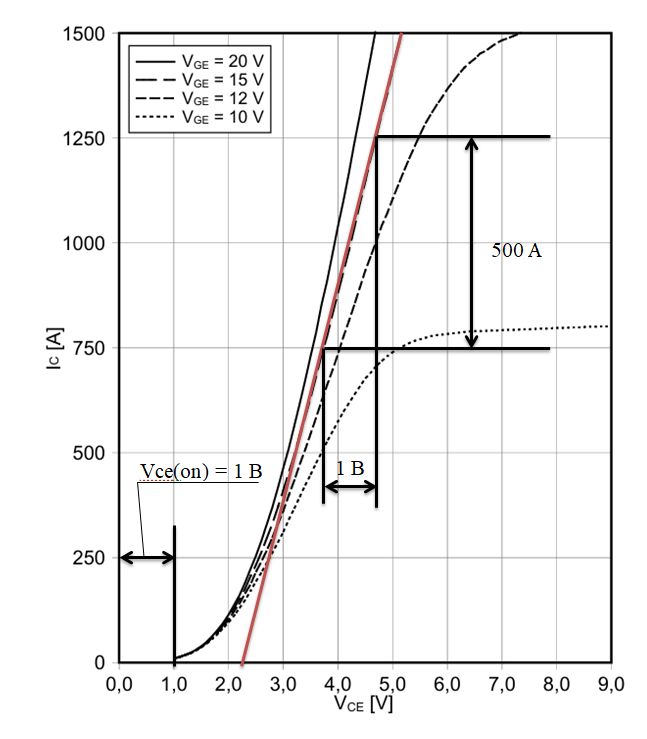

При Vge = 15 V:

deltaI_c = 500; %А.
deltaV_ce = 1; %В.
IGBT.R_on = deltaV_ce/deltaI_c %Ом.

IGBT = struct with fields:
    L_on: 1.8000e-08
    R_on: 0.0020


Forward voltage Vf (V) (Vce(on)):

IGBT.V_f = deltaV_ce;

2) tf (Fall time), мкс.:

Current fall time Tf (s):

IGBT.T_f = 0.5*10^-6;

Current time Tt (s) = Tf (s):

IGBT.T_t = IGBT.T_f;

### 2.4. Параметры силового диода (Diode):

Snubber resistance Rs (Ohms):

Diode.R_s = 5*10^6; 

Остальные параметры силового диода рассчитаны выше.

## **3. Расчёт внешних характеристик ПП:**

На управляющий вход ключевого элемента подаем сигнал от блока «Pulse Generator», в котором задаем величину коэффициента заполнения λ.

Внешние характеристики ПП строим посредством компьютерного моделирования  работы схемы при постоянном коэффициенте заполнения λ с изменением величины сопротивления от максимального значения до минимального, соответствующего номинальному току Iн ТЭД.

Коэффициент заполнения λ в опытах меняем в диапазоне от 0,1 до 0,99 с шагом 0,1  (величина последнего шага равна 0,9).

Открываем модель в Simulink:

open ('SHipVar5_OpVnesh.slx')

Время расчета характеристик в simulink:

timeVnesh = 0.5;
time = timeVnesh;

Параметры проводимых исследований представлены в таблице 1.

Подготавливаем массивы для снятия параметров измерений при Rd_min = 1000 Ом:

Rdmin = 1000;
lamda1 = [];
U2_min = [];
Rd_min = [];
n_op = [];

Задаем шаг с которым будет изменятся значение $\lambda$:

lamdaStep=0.1; %значение шага lamda
lamdamin=0.1; %начальное значение lamda
lamdamax_pred=0.9; %предконечное значение lamda
lamdamax=0.99; %конечное значение lamda
lamda = [lamdamin:lamdaStep:lamdamax_pred lamdamax].';
lamdanumStep=height(lamda) %количество шагов lamda

lamdanumStep = 10

Количество опытов:

OpVnesh.n_op = ([1:1:lamdanumStep]); %количество производимых опытов
n_op = OpVnesh.n_op;

Производим снятие значений U2 при I1min = 0А:

for lam = lamda(1:1:end).' %end - до последнего значения в массиве lamda
    OpVnesh.lamda =  lam;
    Rd.res = Rdmin;
    Rd.ind = (Rd.res/source.f_c)*2;
    sim('SHipVar5_OpVnesh.slx');
    lamda1(end+1) = OpVnesh.lamda(end, 1);
    U2_min(end+1) = round(max(ans.OpVnesh_U2.signals.values(end, 1)),2);
    Rd_min(end+1) = Rd.res(end, 1);
end

Подготавливаем массивы для снятия параметров измерений при Rd_max = $\lambda *\textrm{U1}/\textrm{Iн}$ Ом:

lamda1 = [];
Ld = [];
U2_max = [];
Rd_max = [];

Производим снятие значений U2 при I1 = Iян=Imax:

for lam = lamda(1:1:end).' %end - до последнего значения в массиве lamda
    OpVnesh.lamda =  lam;
    Rdmax = round(lam*(U_1/Imax.current),2);
    Rd.res = Rdmax;
    Rd.ind = (Rd.res/source.f_c)*2;
    sim('SHipVar5_OpVnesh.slx');
    lamda1(end+1) = OpVnesh.lamda(end, 1);
    U2_max(end+1) = round(max(ans.OpVnesh_U2.signals.values(end, 1)),2);
    Rd_max(end+1) = Rd.res(end, 1);
end

Сводим полученные расчеты в единую таблицу:

Таблица №1 – Внешние характеристики ПП:

OpVnesh.T = table(n_op.',lamda1.',U2_min.',U2_max.',Rd_min.',Rd_max.');
OpVnesh.T.Properties.VariableNames = ["№ опыта","lamda","U2,В.(при I=0)","U2,В.(при I=Iян)","Rdmin, Ом.","Rdmax, Ом."];
disp(OpVnesh.T);

    № опыта    lamda    U2,В.(при I=0)    U2,В.(при I=Iян)    Rdmin, Ом.    Rdmax, Ом.
    _______    _____    ______________    ________________    __________    __________

       1        0.1         152.93             152.48            1000          0.44   
       2        0.2         306.65             306.18            1000          0.88   
       3        0.3         460.38             459.88            1000          1.32   
       4        0.4          614.1             613.57            1000          1.76   
       5        0.5         767.83             767.27            1000           2.2   
       6        0.6         921.55             920.97            1000          2.64   
       7        0.7         1075.3             1074.7            1000          3.07   
       8    

По данным таблицы 1 строим внешние характеристики преобразователя:

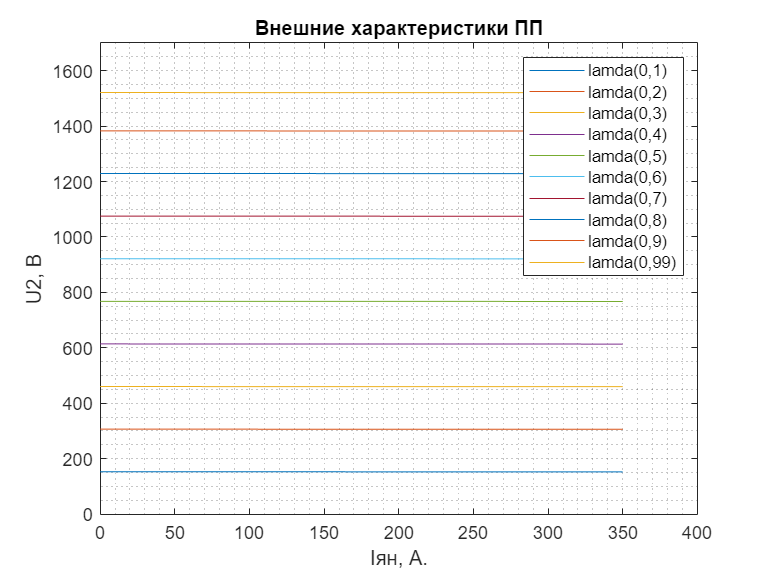

OpVnesh.x1 = [0 Imax.current].';
OpVnesh.y1 = [U2_min(1,1), U2_max(1,1)].';
OpVnesh.y2 = [U2_min(1,2), U2_max(1,2)].';
OpVnesh.y3 = [U2_min(1,3), U2_max(1,3)].';
OpVnesh.y4 = [U2_min(1,4), U2_max(1,4)].';
OpVnesh.y5 = [U2_min(1,5), U2_max(1,5)].';
OpVnesh.y6 = [U2_min(1,6), U2_max(1,6)].';
OpVnesh.y7 = [U2_min(1,7), U2_max(1,7)].';
OpVnesh.y8 = [U2_min(1,8), U2_max(1,8)].';
OpVnesh.y9 = [U2_min(1,9), U2_max(1,9)].';
OpVnesh.y10 = [U2_min(1,10), U2_max(1,10)].';
plot(OpVnesh.x1,OpVnesh.y1,OpVnesh.x1,OpVnesh.y2,OpVnesh.x1,OpVnesh.y3,OpVnesh.x1,OpVnesh.y4,OpVnesh.x1,OpVnesh.y5,OpVnesh.x1,OpVnesh.y6,OpVnesh.x1,OpVnesh.y7,OpVnesh.x1,OpVnesh.y8,OpVnesh.x1,OpVnesh.y9,OpVnesh.x1,OpVnesh.y10);
grid("minor");
xlabel('Iян, А.');
ylabel('U2, В');
title('Внешние характеристики ПП');
legend(["lamda(0,1)","lamda(0,2)","lamda(0,3)","lamda(0,4)","lamda(0,5)","lamda(0,6)","lamda(0,7)","lamda(0,8)","lamda(0,9)","lamda(0,99)"])
xlim([0 400]);
ylim([0 1700]);

## **4. Расчёт регулировочных характеристик ПП:**

Регулировочную характеристику ШИП строим при подключении к схеме блоков «Ramp» и «Subsystem» вместо блока «Pulse Generator».

На управляющий вход ключевого элемента подаем выходной сигнал блока «Subsystem», в котором за счет изменения коэффициента заполнения λ формируются импульсы управления ключевым элементом различной длительности.

Регулировочная характеристика ПП строится посредством компьютерного  моделирования работы схемы.

Коэффициент заполнения λ меняется автоматически.

Открываем модель в Simulink:

open ('SHipVar5_OpReg.slx')

Время расчета характеристик в simulink:

timeReg = inf;
time = timeReg;

Подготавливаем массивы для снятия регулировочной характеристики:

R2 = [];
lamda2 = [];
OpReg.I = [];

Производим снятие значений зависимости тока i1 от коэффициента заполнения λ:

for lam = 1
    R2 = round(lam*(U_1/Imax.current),2);
    Rd.res = R2;
    Rd.ind = (Rd.res/source.f_c)*2;
    sim('SHipVar5_OpReg.slx');
    lamda2 = ans.OpReg_lamda.signals.values;
    OpReg.I = ans.OpReg_i1.signals.values;
end  

Производим построение регулировочной характеристики ШИП:

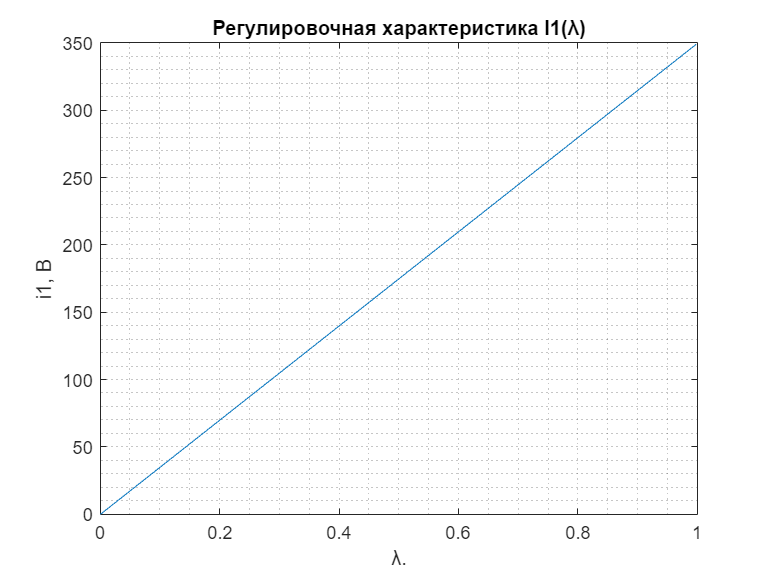

OpReg.x1 = lamda2(1:end).';
OpReg.y1 = OpReg.I(1:end).';
plot(OpReg.x1,OpReg.y1);
grid("minor");
xlabel('λ.');
ylabel('i1, В');
title('Регулировочная характеристика I1(λ)');

## **Заключение**

В ходе выполнения типового задания №2 была разработана математическая модель понижающего  преобразователя (ПП). Определены типы силовых полупроводниковых приборов (IGBT модуля "Infineon FZ750R65KE3" и силового диода " Д543-630") и произведен расчет их параметров. Также в ходе рачета параметров выпрямительных устройст произведен выбор  понизительного и выпрямительного трансформаторов ("ТМН - 16000/110-66" и "ТРДП -12500/ЖУ1" соответственно). Построены нагрузочные и регулировочная характеристики ШИП.